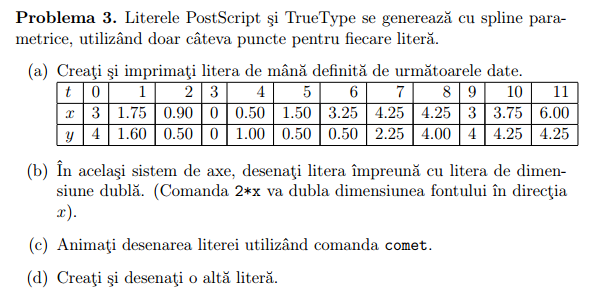

## Parameter and coordinates

t = 0:11;
x = [1.75, 0.90, 0.00, 0.50, 1.50, 3.25, 4.25, 4.25, 3.75, 6.00, 5.75, 4.00];
y = [1.60, 0.50, 0.10, 1.00, 0.50, 0.50, 2.25, 4.00, 4.00, 4.25, 4.25, 2.25];

## Natural parametric splines on each dimension

Sx = spline_natural(t, x);
Sy = spline_natural(t, y);

## Evaluating the splines on a dense grid

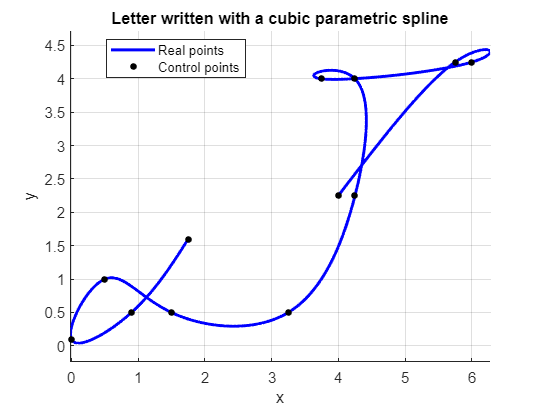

tt = linspace(min(t), max(t), 1000);
xx = Sx(tt);
yy = Sy(tt);

figure; hold on;
plot(xx, yy, 'b-', 'LineWidth', 2, 'DisplayName', 'Real points');
plot(x, y, 'ko', 'MarkerSize', 4, 'MarkerFaceColor', 'k', 'DisplayName', 'Control points');
axis equal;
xlabel('x'); ylabel('y');
legend('Location','best');
title('Letter written with a cubic parametric spline');
grid on;

## The letter double its size on the x-axis

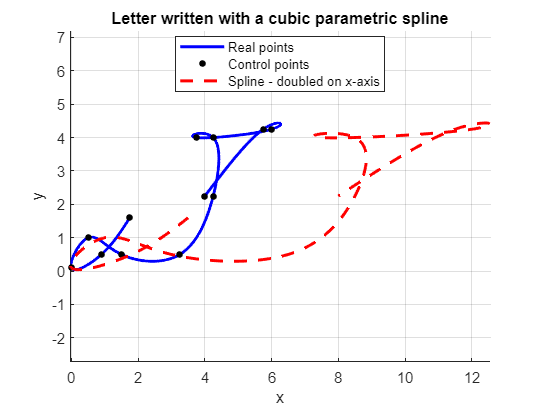

xx2 = 2 * xx;
yy2 = Sy(tt);

plot(xx2, yy2, 'r--', 'LineWidth', 2, 'DisplayName', 'Spline - doubled on x-axis');

## Comet animation

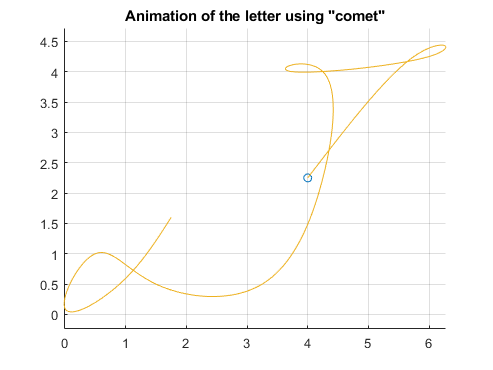

figure;
comet(xx, yy);
title('Animation of the letter using "comet"');
axis equal;
grid on;

## Another letter - W

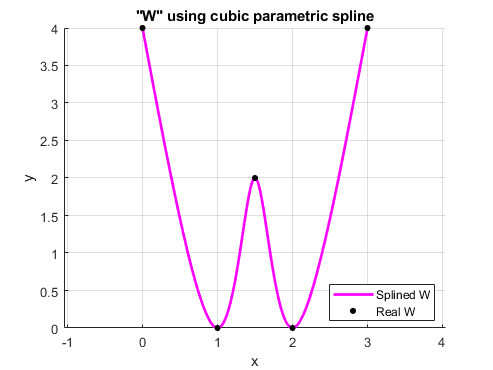

tw = 0:4;
xw = [0, 1, 1.5, 2, 3];
yw = [4, 0, 2, 0, 4];

SWx = spline_natural(tw, xw);
SWy = spline_natural(tw, yw);

ttw = linspace(min(tw), max(tw), 1000);
xxW = SWx(ttw);
yyW = SWy(ttw);

figure;
hold on;
plot(xxW, yyW, 'm-', 'LineWidth', 2, 'DisplayName', 'Splined W');
plot(xw, yw, 'ko', 'MarkerSize', 4, 'MarkerFaceColor', 'k', 'DisplayName', 'Real W');
title('"W" using cubic parametric spline')
legend('Location', 'best');
xlabel('x'); ylabel('y');
axis equal;
grid on; hold off;

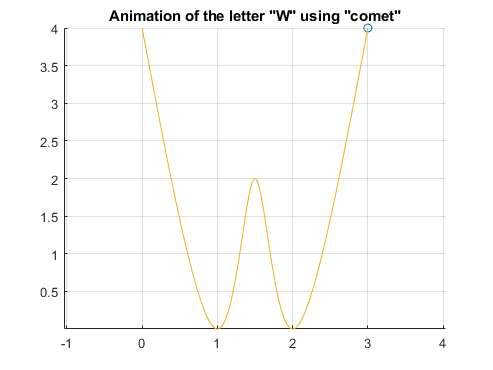

figure;
comet(xxW, yyW);
title('Animation of the letter "W" using "comet"');
axis equal;
grid on;